# **Úvod do MATLAB, Decibel**

## 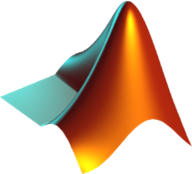

MATLAB je programové prostředí využívající skriptovací programovací jazyk. Jádrem programu je rychlý výpočet matic, které jsou základním datovou strukturou většiny aplikací. Maticových operací lze využít v širokém spektru datové analýzy, simulací a výpočtů. Programové prostředí obsahuje velké množství integrovaných i externích nástaveb pro 2D i 3D vizualizaci dat, tvorby vlastních samospustitelných programů apod. MATLAB je využíván zejména studentskou a vědeckou komunitou, ale své místo nachází i v soukromém sektoru ve vývojových a analytických centrech, kde není prioritou vytvoření konečné aplikace. Ačkoliv mnozí MATLAB nepovažují za samostatný programovací jazyk, tvorba skriptů vyžaduje znalost syntaxe, deklarace proměnných a povědomí o existujících funkcích.

**Užitečné funkce k prostudování (F1, **`doc`**, **`help`**): **`mean, std, median, sum, figure, clc, close, clear, plot, xlabel, ylabel, legend, hold, mldivide, mrdivide, zeros, ones, eye, rand, randn, num2str, size, length, title, disp`

## **1 Úvod do MATLAB:**

Komentář v kódu: %

Komentování jednoho nebo více označených řádků: **Ctrl + R**

Odkomentování jednoho nebo více označených řádků:  **Ctrl + T**

Automatické doplňování kódu: **Tab**

Zarovnání kódu: **Ctrl + I**

Zastavení výpočtu: **Ctrl + C **(při běhu programu, jinak standardně copy)

Pozn.: V MacOS/Liix se zkratky mohou lišit

### **1.1 Seznamte se s prostředím MATLAB**

- Vytvořte si složku a zvolte ji v MATLAB jako pracovní (Current Folder)  . MATLAB při zadání příkazu nejprve pracuje s "Workspace", kde se dívá, jestli v příkazu není zadána proměnná. **Pozor**, lze si takto předefinovat některé existující funkce, které tím nadále nebudou plnit svůj účel (řešitelné smazáním proměnné z "Workspace" = kliknout na proměnnou a potom klávesu delete nebo příkazem v Command Window `clear`).

- Při dalším kroku pracuje matlab právě s "Current Folder", kde můžete mít nadefinované vlastní funkce (stejně jako u proměnných, lze si tímto předefinovat některé existující funkce).

- Na závěr MATLAB prochází jednotlivé složky, které jsou uloženy v "Set Path" (viz další bod). V této části jsou vidět všechny nainstalované ToolBoxy. Můžete si vytvořit složku, kde si budete ukládat data, ke kterým budete potřebovat přistupovat z několika různých skriptů. Tím, že složku s daty přidáte do "Set Path", budete mít přístup k datům ze všech Vašich skriptů. Složky se zde prochází v pořadí jak jsou seřazeny odshora dolů. Protože se funkce volají přímo jménem a nikoli jako v Pythonu, kde se importuje knihovna nebo přímo funkce, nastává zde nevýhoda MATLABu při definování stejného jména funkce. V takovém případě se volá první nalezená funkce.

- 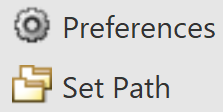 V "Preferences" si můžete nastavit vizuál prostředí MATLAB ale také nastavení ToolBoxů. Vzhledem k obrázkům bez pozadí si nenastavujte pozadí na černo, protože byste potom neviděli popisky grafů přiložených v live skriptu.

- Nový skript m-file (*.m) lze vytvořit pomocí ikony:

-  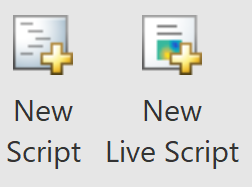 Pro samostatné funkce, které budete volat v jiných skriptech, je výhodnější klasický script místo live skriptu.

- Zde v live scriptu v záložce "VIEW" si zaškrtněte "Output Inline". Při původním nastavení "Output on Right" se Vám bude výstup (výpočty, grafy) zobrazovat napravo od kódu, což při malém rozlišení monitoru může být velice nepřehledné.

- 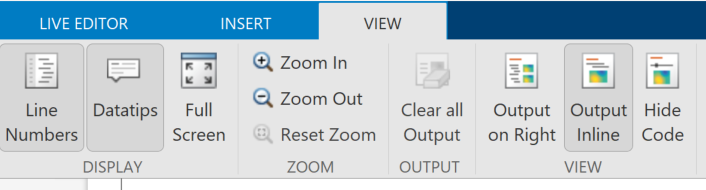

- Příkazy můžete zadávat přímo v Command Window (a=10). Funkce pwd vypíše cestu do pracovního adresáře.

- Části kódu lze spouštět i z editoru označením textu a stiskem (F9 pro Windows; Shift+F7 pro MacOS). Např. označte následující text a vyzkoušejte: 

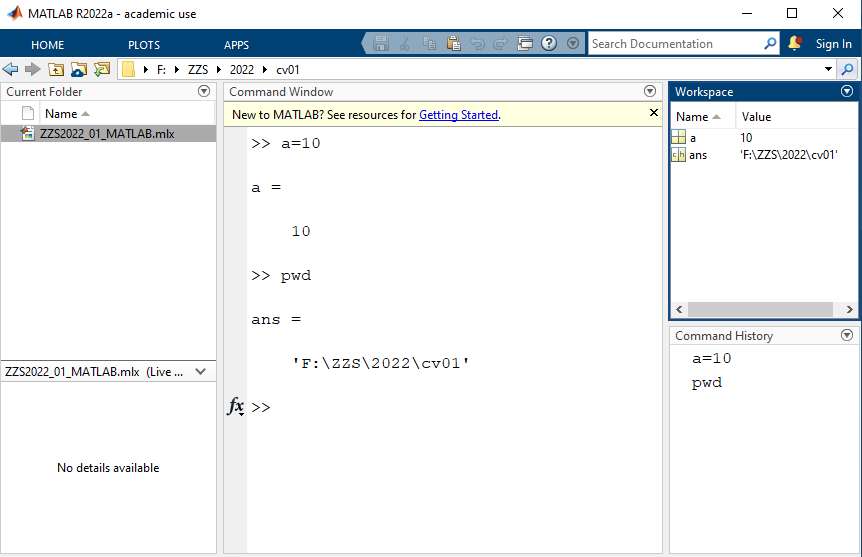

**Spuštění bloku kódů se provádí modrým panelem vlevo nebo Ctrl + Entr označené buňky:**

disp('Hello word!')

V případě livescriptu se výstup zobrazí v editoru. V případě práce v m-file se vypisuje v Command Window. 

Mezi kódem a prostým textem můžete přepínat v záložce "LIVE EDITOR" pomocí tlačítek Code / Text.

Spuštění všech bloků (celého skriptu) využijte tlačítko na kartě editor "Run":  

### 1.2 Práce s vektory a maticemi

Sledujte Workspace, kde se jednotlivé proměnné vytvářejí. Proměnná nesmí začínat číslici, ale může ji obsahovat.

a=10 % skalární hodnota

Při zápise bez středníku na konci řádku se hodnota vypíše. Se zápisem se středníkem se proměnná pouze vytvoří (budeme v budoucnu preferovat). Text za % je komentář. %% odděluje celý blok (platí i pro scripty *.m, zde oddělí plnou čárou).

b=[1,2,3,4]; % řádkový vektor (zápis mezerou)
c=[1 2 3 4] % řádkový vektor (ekvivalentní zápis)
% pokud je na konci řádku ";" znamená to, že výstup se nevypíše v Command
% Window => při kontrole konkrétního výsledku nemusí být zapsán ";",
% nicméně při tvoření signálu o 10 000 vzorků doporučeno.

 Vytvořte sloupcový vektor, hodnoty se oddělují středníkem.

d=[1;2;3;4] 

Vytvořte řádkový vektor d1 s hodnotami: 10 20 30:

d1 = [10 20 30]

Vytvořte sloupcový vektor d2 s hodnotami: 10 20 30:

d2 = [10;20;30]

Zápis matic využívá spojení řádkových a sloupcových vektorů. Čárka/mezera vedle sebe, středník pod sebe.

e=[1 2 3 4; 11 12 13 14] % [řádek ; řádek]
% alternativní zápis:
f=[[1 2 3 4];[11 12 13 14]] % jiný zápis
g=[[1;11],[2;12],[3;13],[4;14]] % [sloupec, sloupec, sloupec, sloupec]

**Vytvořte matici g1 (3x4)**

g1 = [9 8 7 6; 0 0 0 0; 1 1 1 1]

Skládání matic a vektorů využívá i symbolické reprezentace proměnných

% skládání matic
x=[10 20 30 40 50] % řádkový vektor 1x5
y=[0.1 0.2 0.3 0.4 0.5] % řádkový vektor 1x5
 
XY_matice=[x;y] % matice: řádek y pod řádkem x
XY_vektor=[x,y] % vektor: x následovaný y


Transpozice (')

% Hermitovská transpozice (u komplexních čísel budou po transpozici čísla komplexně sdružená)
ct=c' % transpozice vektoru c
et=e' % transpozice matice e
% Transpozice bez komplexního sdružení:
ct=c.';
et=e.';

Geneze lineárně roustoucích/klesajících hodnot vektorů (:). Číselné hodnoty opět můžeme nahradit i symbolem jiné proměnné.

h=1:10 % od 1 do 10 s krokem 1
ii=1:1:10 % od 1 do 10 s krokem 1; i a j se používají jako imaginární jednotky pro komplexní čísla
jj=10:2:20 % od 10 do 20 s krokem 2
k=10:2:19 % od 10 do 19 s krokem 2 (jaká je poslední hodnota?)
l=10:-1:1 % od 10 do 1 s krokem (-1)

pocatek=10;
krok=10;
konec=100;
m=pocatek:krok:konec % od 10 do 100 s krokem 10

Generovaní vektorů a matic pomocí funkcí

n=linspace(0,10,5) % řádkový vektor od 0 do 10 v pěti bodech

**Pomocí skládání generování, transpozice a skládání vektorů vytvořte matici N1 (10x3), kde první sloupec bude nabývat hodnot v intervalu 1 až 10, druhý sloupec 100 až 10 a třetí sloupec 3 až 6.**

a = 1:10;
b = 100:-10:10;
c = linspace(3,6,10);
N1 = [a' b' c']

Generování speciálních typů vektorů a matic.

o=eye(5) % jednotková matice 5x5
p=ones(5) % jedničková matice 5x5
q=ones(5,3) % jedničková matice 5x3
r=zeros(5,3,2) % nulová matice 5x3x2
 
s=rand(3,5) % matice náhodných čísel 3x5 (rovnoměrná distribuce 0-1)
s15=(5-1)*rand(3,5)+1 % matice náhodných čísel 3x5 (rovnoměrná distribuce čísel od 1 do 5)
t=randn(3,5) % matice náhodných čísel 3x5 (Gaussovská/normální distribuce)

mg = magic(4) % vytvoří matici N×N (4×4) pro N>3 o prvcích 1 až N^2
% - ideální na rychlé pokusy (např. s indexací)

Výběr prvků přímým indexováním.

u=10:2:30 % vektor
v=u(1) % 1. prvek vektoru
w=u([1 2 3]) % 1., 2. a 3. prvky vektoru
 
x=u(1:3) % 1. až 3. prvek (krok 1)
y=u(5:-1:1) % 5., 4., 3., 2. a 1.
 
z=u(10:end) % od 10. prvku až po konec s krokem 1
u_rev=u(end:-1:1) % vektor u pozpátku

**Indexování matic pomocí souřadnic** (subscripts)

A=rand(10,5) 

A =     0.5167    0.0637    0.2662    0.5854    0.1045
    0.1519    0.4255    0.2915    0.1190    0.7002
    0.3807    0.4043    0.1884    0.9265    0.3958
    0.8210    0.4003    0.0229    0.5936    0.0849
    0.1714    0.1119    0.4494    0.8836    0.2145
    0.3300    0.4243    0.2436    0.4245    0.2488
    0.9665    0.6135    0.8687    0.6073    0.2267
    0.8063    0.9881    0.5286    0.0708    0.7030
    0.2222    0.2199    0.9141    0.9248    0.7542
    0.9998    0.3541    0.9739    0.6421    0.5473


B=A(5,2); % hodnota na 5. řádku a 2. sloupci
C=A(6:end,1); % hodnoty od 6. řádku po poslední v prvním sloupci
D1=A(8,:); % všechny hodnoty 8. řádku
D2=A(:,[2 4]); % všechny hodnoty 2. a 4. sloupce
E=A(1:7,4:5); % submatice mezi 1. až 7. řádkem a 4. až 5. sloupcem
 
F=A([1 3],1:3) % matice složená z 1. a 3. řádku mezi 1. a 3. sloupcem

F =     0.5167    0.0637    0.2662
    0.3807    0.4043    0.1884


**Indexování matic dle pořadí prvku** (linear indices)

G=A(1:25); % vektor hodnot z prvních dvou sloupců (10+10) + 5 prvků 3. sloupce (+5), tj. vypíše prvních 25 prvků matice

**Logické indexování.** Vybere prvky, kde je `true` (1), vynechá `false` (0).

I=10:2:30; % vektor hodnot
idx=I>20; % prvky větší než 20;
 
J=I(idx); % pouze prvky, kde na pozici je true, tj. >20;
K=I(I>20) % ekvivalentní zápis

K =     22    24    26    28    30


**Z matice A vyberte prvky 2. a 5. řádku a uložte do proměnné A1**

A1 = A([2 5], :)

A1 =     0.1519    0.4255    0.2915    0.1190    0.7002
    0.1714    0.1119    0.4494    0.8836    0.2145


**Z matice A vyberte pouze rohové prvky a uložte je do proměnné A2 (existuje více způsobů, jak to udělat)**

A2 = A([1 end], [1 end])

A2 =     0.5167    0.1045
    0.9998    0.5473


**V matice MG prohoďte 1. sloupec s 3. sloupcem použitím *****indexace*****.**

MG=magic(5);
MG = MG(:,[3 2 1 4 5])

MG =      1    24    17     8    15
     7     5    23    14    16
    13     6     4    20    22
    19    12    10    21     3
    25    18    11     2     9


***Nastudujte si funkce *****(příkaz **`doc`**, F1)**: `reshape, eye`

`Pozn.:` Všimněte si, jakého typu je výstup funkce `eye` a proto jej nelze přímo použít jako indexace. Indexovat lze pouze logickou proměnnou (True/False) nebo čísly 1, 2, .., N×M, kde N je počet řádků a M je počet sloupců matice (případně rozšířeno o další dimenze matice).

**Vytvořte matici G (5x5) obsahující v řádcích hodnoty od 1 do 25. Pomocí ****logických operací a jednotkové matice **`eye`** vyberte prvky na digonále a uložte jako vektor G1.** V praxi lze použít také funkce `diag`.

G = 1:25;
G = reshape(G,[5 5])'

G =      1     2     3     4     5
     6     7     8     9    10
    11    12    13    14    15
    16    17    18    19    20
    21    22    23    24    25


idx = eye(5)==1;
G1 = G(idx)

G1 =      1
     7
    13
    19
    25


%...



Zápis prvků do matice využívá stejných pravidel indexování jako jsme používali výše: přímé, symbolické, logické.

Pro vektory nebo matice dle pořadí.

L=10:20
L(L>=15)=Inf % kde je L>15, nahraď nekonečnem
L(1:2)=0 % na 1. a 2. místo zapiš nulu
L(2:5)=[1 2 3 4] % 2. až 5. prvek nahraď vektorem
L(L>4)=[] % tam, kde je hodnota >4, vlož prázdnou hodnotu, tj. vymaž prvek 

Pro matice indexováním souřadnic

LL=[1 2 3; 4 5 6; 7 8 9; 10 11 12]
LL(1:3,end)=100 % 1. až 3. řádek posledního sloupce nahraď hodnotou 100

**Vygenerujte nulovou matici L1(6x6) a do čtvrtého kvadrantu (vpravo dole) vložte jednotkovou matici (3x3). Využijte funkcí **`zeros`** a **`eye.`

L1 = zeros(6);
L1(4:6,4:6) = eye(3)

Matematické operace. Sčítání (+), odčítání (-) a skalární násobení (.*) se provádí pro jednotlivé prvky matic, proto musí souhlasit jejich velikost, nebo alespoň rozměr v jedné dimenzi. Vyjímkou je operace s maticí a konstantou.

M=[1 2 3 4]
N=[11 12 13 14]
 
O=M+N % velikost matic musí souhlasit
OO=M+10 % každému prvku M se přičte 10
P=N-M % velikost matic musí souhlasit

% skalární násobení (po prvku)
Q=M.*N
S=M*10 % každý prvek M vynásobený 10

% dělení (po prvku)
T=N./M
U=M/10 % každý prvek M vydělený 10

% 3. mocnina po prvku
V=M.^3

% 2. odmocnina po prvku
W=M.^(1/2)


Operace matic jiných velikostí, ale stejným rozměrem v jedné z dimenzí.

M24=[M;N] % 2x4
K21=[2;10] % 2x1

O24=M24+K21 % ke každému sloupci matice M24 přičte vektor K21
P24=M24.*K21 % každý prvek sloupec matice M24 je násoben prvkem z K21 


Vektorové násobení.  

%X=M*N % Error: oba jsou řádkové, matice nelze vynásobit - po vyzkoušení zakomentujte

Je potřeba, aby počet sloupců M byl shodný s počtem řádků N. Budˇ tedy transponujte N a vznikne skalární součin (skalár), nebo transponujte M a vznikne dyáda (outer product) o rozměru 4x4.

U násobení matic platí obdobná pravidla. Operace vrací matici jednotlivých vektorových násobení

Y=M24*M24'

Vektorové dělení.

Z lineární algebry víme, že operace maticového dělení je násobením s inverzní maticí:

MM = randn([4 4])   % matice náhodných čísel 4x4 

MM =     0.5602    0.9374   -0.9668   -1.6838
   -0.3090    0.9742   -0.4712    0.1770
   -0.3676   -2.1189    1.7352   -0.1245
    0.3656   -0.0465   -0.7775   -0.4156


NN = randn([4 4])   % matice náhodných čísel 4x4

NN =     0.8795    0.3501    0.3397    0.9973
    0.5661   -0.2913   -0.6728   -0.0261
    0.3759    0.1861   -0.5370   -0.6570
   -0.2770    0.5766   -1.0402    0.6777



% U=inv(M)*N;
Z=MM\NN % též funkce mldivide (ml ~ multiply from left by inverse matrix)

Z =    -1.7623   -0.0456    3.9810    0.1956
    0.2316   -0.5833    1.8389   -0.2074
    0.0537   -0.6281    2.8173   -0.6114
   -1.0105   -0.1872    0.5289   -0.2916


 
% V=N*inv(M);
ZZ=NN/MM % též funkce mrdivide (mr ~ multiply from right by inverse matrix)

ZZ =    -0.3014   -3.6479   -1.9285   -2.1551
   -0.2528   -0.8419   -0.3799    0.8420
    0.2954   -0.2342   -0.0715    0.3057
   -0.6067    1.3744    0.0608    1.3948


Tento zápis s použitím operátorů `\, /` je v MATLAB efektivnější a přesnější než výpočet pomocí inverzní matice a násobení.

**Vyřešte maticově soustvu rovnic o dvou neznámých x1 a x2 ****bez funkce inv****.**


$$\begin{array}{l}
2x_1 +x_2 =3\\
{\;\;x}_1 -x_2 =2
\end{array}$$


**Převedeme do maticového zápisu**


$$\left\lbrack \begin{array}{cc}
a_{11}  & a_{12} \\
a_{21}  & a_{22} 
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
b_1 \\
b_2 
\end{array}\right\rbrack ;a\in \mathbf{A},x\in \mathbf{X},b\in \mathbf{B}$$
 


$$\begin{array}{l}
\mathbf{Ax}=\mathbf{B}\\
\mathbf{x}={\mathbf{A}}^{-1} \mathbf{B}
\end{array}$$


AA = [2 1 ; 1 -1];
BB = [3 ; 2];
xx = AA\BB

xx =     1.6667
   -0.3333


### 1.3 Tvorba x-y grafu

MATLAB obsahuje desítky [typů grafů](https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html) (lze označit proměnnou ve Workspace a následně v záložce PLOTS vybrat požadovaný graf).

My si prozatím vystačíme spojnicovým X-Y realizovaný funkcí `plot`. Detaily naleznete v dokumentaci.

Funkce může mít jeden, dva nebo i více vstupů, tak jako většina MATLAB funkcí. Chování se poté může významně lišit, nebo umožňuje mnoho dalších nastavení. Proto je třeba pozorně studovat dokumentaci.

Grafy můžeme vytvářet v jednotlivých oknech - figure. Jednotlivé figury lze rozdělit do sekcí - subplot. Graf poté vykreslujeme v daném subplot. Toto členění oceníte zejména u psaní vlastního kódu v m-files (*.m). V livescript (*.mlx) se zobrazuje výstup uvnitř skriptu.

figure(1); % vytvoří okno s číslem 1
clf; % vyčistí figuru 1, pokud něco obsahuje z předchozího spuštění
subplot(1,2,1) % vytvoří 2 podokna, 1 řádek, 2 sloupce. Poslední parametr je místo, kam budu zapisovat

Zobrazme si čáru spojující dva o souřadnicích [0 0] a [2 3]

x=[0 2]; % x
y=[0 3]; % y=f(x)
plot(x,y) %

Pokud bychom do funkce zadali pouze jedne vstup y, hodnoty x by se předpokládaly dle pořadí [1 2]. Barva nového grafu se volí automaticky.

hold on % umožní uchování předchozího grafu a přidá do stejného grafu nový 
plot(y) % zobrazí hodnoty y, ale za x dá pořadí 1 2 ...
hold off % při opětovném spuštění skriptu by se přidávalo znovu proměnné do obrázku,
% hold off vypne přidávání dalších grafů

Přidáme popisky os:

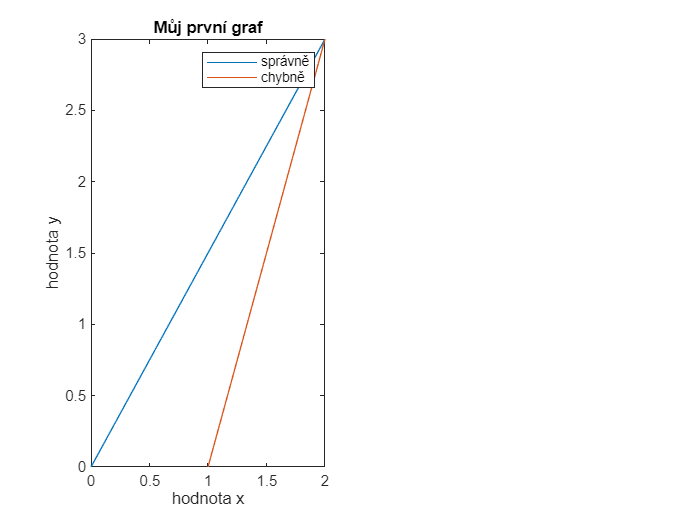

xlabel('hodnota x')
ylabel('hodnota y')
title('Můj první graf')
legend('správně','chybně') % přidá legendu

Pozn.: Popisy os a nadpis se nastavuje pro každý graf v subplot zvlášť.

Pozn. pro zájemce: Od verze MATLAB 2019b existuje alternativní způsob tvorby grafů a podgrafů pomocí funkcí `tiledlayout` a `nexttile`. Pro většinu běžných grafů jsou oba způsoby stejně vhodné, `tiledlayout` může být výhodnější u tvorby složitých grafů s více podgrafy a různými typy grafů. Je na Vás, který způsob budete využívat, v zadáních úkolů bude využit klasický způsob pomocí `figure` a `subplot`. 

Nyní to zkusme znovu a do druhého podokna vykreslíme X-Y graf výsledku soustavy dvou rovnic z předchozí úlohy. Jedná se vlastně o parametrické vyjádření přímky.


$$y=1\ldotp 6667x-0\ldotp 3333$$


Nyní si můžeme zvolit libovolné souřadnice x a vykreslíme k nim hodnotu y. Další parametry se mohou zadávat ve zkratkách, viz dokumentace. Můžete ale nastavit složitější parametry v [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html?s_tid=srchtitle_Line%20Properties_1)

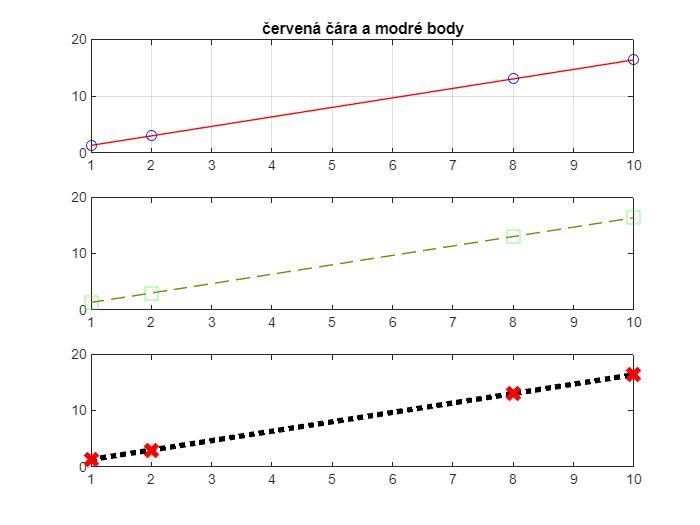

x=[1 2 8 10];
y=1.6667*x-0.33;
figure(2)
subplot(3,1,1)
plot(x,y,'r') % písmenný třetí operátor definuje bravu (r-red)

hold on
plot(x,y,'ob') % 'o' zobrazí body bez spojnice, (b-blue)
hold off
grid on % rastr
title('červená čára a modré body')

subplot(3,1,2)
plot(x,y,'Color',[0.5 0.5 0],'LineStyle','--','Marker','s','MarkerSize',10,'MarkerEdgeColor','g')
% typ LineStyle, Marker a Color lze napsat rovnou jako jeden samostatný parametr
% hned po vypsání os
subplot(3,1,3)
plot(x,y,':xk','MarkerSize',10,'MarkerEdgeColor','r','LineWidth',3.2)% LineWidth nastaví šířku čáry, zde na velikost 3.2 bodu

### **1.4 Tvorba vlastních funkcí**

Při tvorbě [vlastních funkcí](https://www.mathworks.com/help/matlab/ref/function.html) se nejčastěji využívá m-file (*.m), který se musí jmenovat stejně jako jako volaná funkce.

Vytvořte nový skript: 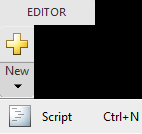.

Na první řádek  vytvoříte hlavičku funkce, její výtupy, název a vstupy:

Nyní si vytvořte funkci `kos_prumer.m`, která bude počítat ze zadaných známek `c `a kreditů `w` za předmět vážený průměr známek. Doplňte vnitřní kód funkce, který spočítá výstupy `avr` (aritmetický průměr), `sd` (směrodatnou odchylku), `med` (medián) a `wavr` (vážený průměr). Nalezněte v dokumentoci vhodné funkce, které `avr`, `sd` a `med` počítají. Pro výpočet váženého průměru `wavr` využijte skalárního násobení/dělení a funkce sumy.


$$W=\frac{\sum_{n=1}^N w\left(n\right)c\left(n\right)}{\sum_{n=1}^N w\left(n\right)},\mathrm{kde}\;W\;\mathrm{je}\;\mathrm{vážený}\;\mathrm{průměr},c\;\mathrm{hodnota},w\;\mathrm{její}\;\mathrm{váha}\;a\;N\;\mathrm{počet}\;\mathrm{průměrovaných}\;\mathrm{hodnot}$$


 Funkci uložte do pracovního adresáře jako `kos_prumer.m`.

Nyní si vytvořte vektor c známek a odpovídajících kreditů w a funkci zavolejte:

c=[1 2 3 4 5];
w=[1 1 8 9 4];
[avr,sd,med,wavr]=kos_prumer(c,w);

avg = 3

sd = 0.9664

med = 3

wavr = 3.6087

**Pozn.**

V drtivé většině případů si budete vytvářet vlastní funkce a ukládat je jako samostatné .m soubory. Ty budete volat z příkazového řádku nebo jiného skriptu *(*.mlx nebo .m). Vyjímkou však mohou být jednoduché a jednorázově používané funkce, které lze do skriptu vložit jako anonymní funkci *@fun* před tím, než ji voláme. 

Lze vytvářet anonymní funkce podobně jako v jazyce Python (lambda x:).

Pozn.: Pokud chceme mít funkci (jako je např. vytvořená `kos_prumer`) součástí spouštěného skriptu, musí být kód funkce vložena až na konci skriptu, avšak skript nelze poté spouštět po sekcích, ale jen jako celek.

## **2 Decibel [dB]**

### **2.1 Úvod - Decibel**

Ačkoli jednotka "bel", respektive "decibel", nepatří do jednotek SI, je v technice široce využívaná kvůli logaritmické škále. Původně vznikla pro popis lidského sluchu, protože subjektivní vnímání člověka není lineární, nýbrž logaritmické. Člověk je schopen vnímat intenzitu zvuku od sotva slyšitelného šumu (práh slyšení) až po extrémní hluk (na prahu bolesti). Hranice slyšitelnosti odpovídá akustické intenzitě zhruba 1 $\mathrm{pW/m^2}$ pro 1 kHz tón.

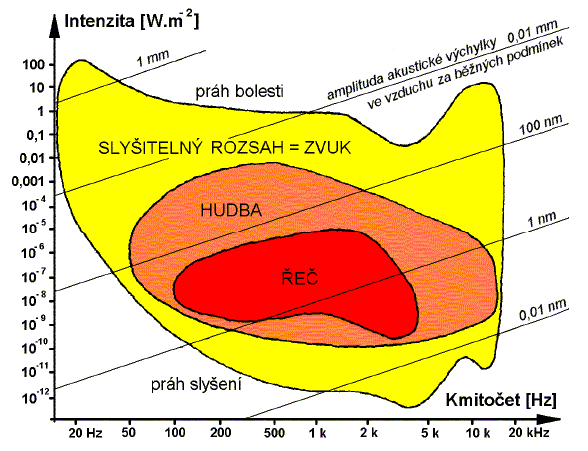

Zdroj: [Česká komora autorizovaných inženýrů a techniků činných ve výstavbě](https://profesis.ckait.cz/dokumenty-ckait/tp-1-8-3/)

Při výpočtu dB se využívá vzorce:


$$Výsledek [dB] = {10}\cdot\log_{10}\frac{Měření}{Reference} [-]$$


Poměr proměnné (měřené) veličiny a její reference mají stejnou jednotku, je tedy logaritmován jejich bezrozměrný poměr. **Decibel je tedy ve výsledku také bezrozměrný** (stejně jako např. procenta). 

Na frekvenci 1 kHz je člověk schopen od sebe rozeznat dvě různé intenzity hlasitosti právě s odstupem 0,1 bel (0,1 B). Pro snadnější zápis hodnot v celých číslech se zavedla podjednotka "decibel"  (0,1 B = 1 dB), který je dosažen násobením logaritmu deseti ve vzorci.

Pozn.: V různých aplikacích se můžeme setkávat s dalšími variantami značení dB, kdy doplňuje i hodnotu použité reference. Například pro referenci v miliwattech (mW) se využívá značení dBm, zisk antény dBi aj.

**Spočtěte a odpovězte:**

**1) Převod na dB. Referenční hodnota je dle definice 1 **$\mathrm{pW/m^2}$**. Kolik je 100 **$\mathrm{pW/m^2}$ **v dB?**

** Funkce:** `log, exp, log10, disp`

Přepočtěte 100 $\mathrm{pW/m^2}$ na dB:

vykon_db = 10*log10(100/1)

vykon_db = 20

**2) Převod z dB. Pokud 0 dB odpovídá 1 **$\mathrm{pW/m^2}$**, kolik je 130 dB v **$\mathrm{pW/m^2}$**? Výpočet proveďte v MATLABu.  **

Převod z decibelů provedeme odlogaritmováním $\log_{10} X\approx {10}^X$:


$$\mathrm{Měření}\;\left\lbrack \frac{\mathrm{pW}}{m^2 }\right\rbrack =Reference\cdot {10}^{\frac{\mathrm{Výsledek}\;\left\lbrace \mathrm{dB}\right\rbrace }{10}}$$


Pozn.: desetina v exponentu odpovídá převodu z decibel na bel.

mereni = 1*10^(130*0.1)

mereni = 3.9811

**3) Zde stačí napsat přímo odpověď **(např.** 5krát větší**, atd.)**.**

**    a) Výsledek je **$-$**3 dB. Kolikrát je výstupní výkon menší / větší oproti vstupu?**

        poloviční (0,5012krát)

**    b) Výsledek je 10 dB. Kolikrát je výstupní výkon menší / větší oproti vstupu?**

        10krát vetší

**    c) Výsledek je 20 dB. Kolikrát je výstupní výkon menší / větší oproti vstupu?**

        100krát větší

#### 2.1.1 Hodnota 3 dB

U sluchu jsou 3 dB minimální hodnotou intenzity, kdy je člověk schopen rozlišit hlasitost **dvou hladin šumu** (oproti 1 dB pro 1 kHz tón). Tato hodnota je velice subjektivní a někdy se uvádí i vyšší hodnota (např. 5 dB, [můžete vyzkoušet sami](https://www.youtube.com/watch?v=uCnsw9oRDsM)). Je to hodnota, kdy se obecně **výkon** zvýší dvakrát (+3 dB), resp. zmenší na polovinu (-3 dB), tj. v závislosti na znamínku => odpověď u otázky 3.a budou mít všichni správně! :). V technice se tato hodnota ustálila jako arbitrární práh, který např. definuje místo zlomového kmitočtu u filtrů (např. RC, LC články apod., detailněji v dalších týdnech).

#### **2.1.2 Signal to Noise Ratio (SNR)**

V měření, záznamu a reprodukci signálu je vždy užitečná informace zkreslená všudypřítomným šumem. Pro kvantifikaci poměru informace a šumu se používá hodnota **Signal to Noise Ratio (SNR)**, česky **odstup signálu od šumu**, která vyjadřuje poměr **výkonu** užitečného signálu od **výkonu** šumu. Rozdíl mezi signálem a šumem chceme co největší (tj. maximálně potlačit šum). Hodnota SNR může tedy nabývat hodnot v široké škále, proto s výhodou také převádíme logaritmem na dB. Podobně jako u úpravy jednoty dB podle použité reference, i značení SNR se upravuje pro konkrétní případ o jaký šum se jedná. Např. pro kvantizační šum se veličina značí SNRQ. Výpočet se pro konkrétní případ také může upravovat nebo zjednodušovat, platí ale základní definovaný výše uvedený vzorec.

#### 2.1.3 Decibely v nevýkonných veličinách

Hodnoty dB jsou vždy definovány pro poměr veličin výkonu. Avšak v mnoha aplikacích je využíván poměr nevýkonných veličin, např. napěťové nebo proudové zesílení zesilovače $\left(\frac{U_{\textrm{out}} }{U_{\textrm{in}} },\;\frac{I_{\textrm{out}} }{I_{\textrm{in}} }\right)$, přenos systému apod. 

Např. elektrické napětí je veličina práce. Proto musíme vzorec výpočtu upravit, pokud chceme vypočítat hodnoty poměru napětí v dB. Elektrický výkon (*P*) je spočten jako násobek napětí (*U*) a proudu (*I*). Protože v biologických signálech většinou měříme jen jednu veličinu (typicky elektrický potenciál, tj. napětí), dosadíme za proud pomocí Ohmova zákona výpočet proudu pomocí elektrického odporu:


$$P = U\cdot I = U\cdot \left( U/ R \right) = U^{2}/R$$


Výsledek dosadíme do původního vzorce:


$$Proměnná [dB] = 10\cdot\log_{10}\left(\frac{U^{2}_{Měření}/R [W]}{U^{2}_{Reference}/R[W]}\right) = 10\cdot\log_{10}\left(\frac{U_{Měření}[V]}{ U_{Reference}[V]}\right)^{2} = 20\cdot\log_{10}\left(\frac{U_{Měření}[V]}{ U_{Reference}[V]}\right)$$


Všimněte si, že kvadrát napětí se přesune před logaritmus, který je pro nevýkonných veličiny násoben 20. Dostáváme tak vzorec $X\;\left\lbrack \textrm{dB}\right\rbrack =20\cdot \log_{10} \;\left(X\right)$.

Referenci bereme většinou 1 V (pokud není uvedeno jinak). Potom lze měřené napětí uvádět v dB:


$$U_{Měření} [dB] = 20\cdot\log_{10}U_{Měření} [V]$$


Obdobně přenos systému (např. zesílení zesilovače, útlum filtru) zapisujeme v dB, kde referenční hodnotu reprezentuje hodnota na vtupu a měřená na výstupu $A=\frac{U_{\textrm{out}} }{U_{\textrm{in}} }$ apod.:


$$A\;\left\lbrack \textrm{dB}\right\rbrack =20\cdot \log_{10} A$$


**Odpovězte (opět stačí rovnou slovně, pokud jste si jistí na 100 %):**

**1) Jaké hodnotě napětí odpovídá hodnotě 3 dB při referenci **$1$**V?**

2V

**2) Jaké hodnotě napětí odpovídá hodnotě 6 dB při referenci **$1$**V?**

**3,98V  (vypočet v přikladu 2) Převod z dB)**

**3) Zesilovač zesílí vstupní napětí 10.000**$\times$**. Jaký je zisk zesilovače v dB?**

40dB

### **2.2 Cvičení**

**Načtěte signál a vytvořte grafy podle vzoru.**

**1)**

**Nápověda: **`log10, figure, subplot, plot, hold, xlim, xlabel, ylim, ylabel, grid, legend, title`

Napěťový průběh jako takový v praxi **nebudeme** převádět na dB. Cílem je zde vyzkoušet a procvičit si převod na dB a vykreslení grafů v MATLABu. Později budeme převod a toto vykreslení využívat u filtrů.

**Načtení signálu z .mat souboru lze udělat přímo v kódu.** Musíte ale mít soubor vidět v "Current Folder" nebo pomocí "Set Path" nastavit cestu k datům (viz úvod).

%%% Načtení dat
load ZZS_cv01_data.mat
%% Soubor obsahuje jednu proměnnou y, která reprezentuje napětí ve Voltech.
%% Osu x můžete vygenerovat jako vektor nebo na přímo vykreslit hodnoty do
%% plot.
% x = 1:length(y);

**Vytvořte graf podle vzoru**

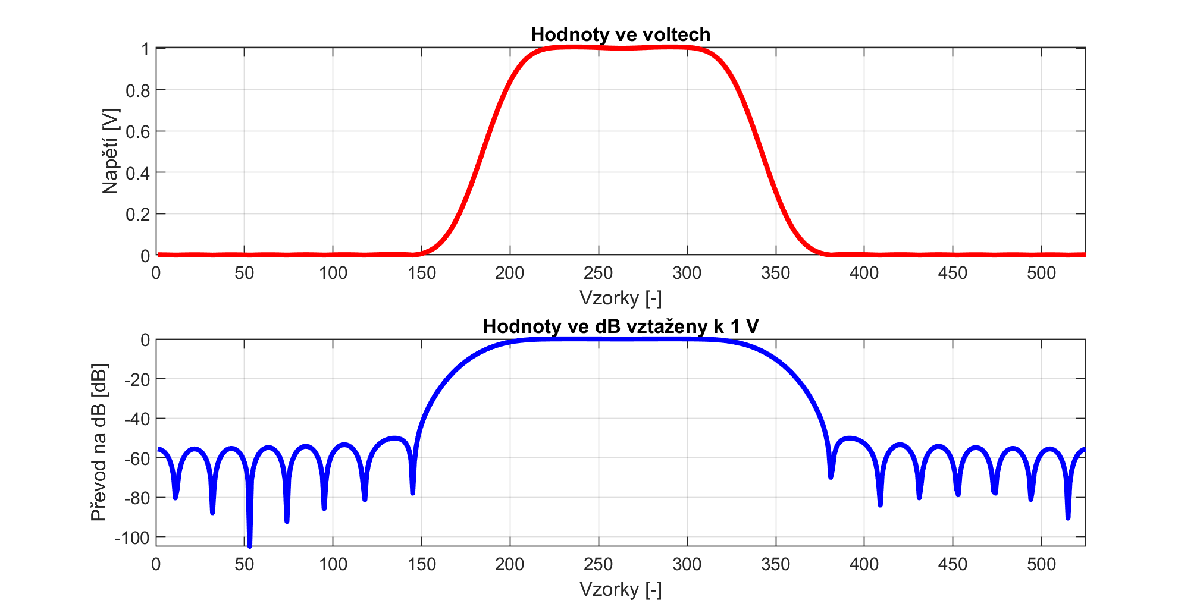

**Obrázek má dva subploty.**

- **První subplot má hodnoty ve Voltech (přímo samotná proměnná y) bude červenou barvou s šířkou čáry 2.5.**

- **Druhý subplot má hodnoty ve dB (nutno převést ***y*** na dB podle posledního ****vztahu uvedeného v 2.1.3****) bude modrou barvou s šířkou čáry 2.5.**

**Popište osy a nadpis grafu, nastavte limity osy x od 0 po 525 a vykreslete rastr.**

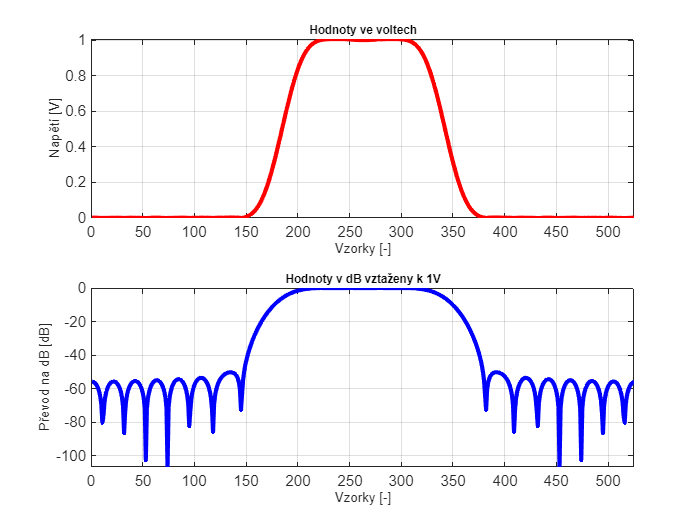

figure(3)

subplot(2,1,1)
plot(y,"LineWidth",2.5,"Color","r")
xlim([0 525])
grid on
title("Hodnoty ve voltech", "FontSize",7)
ylabel("Napětí [V]", "FontSize",8)
xlabel("Vzorky [-]", FontSize=8)


subplot(2,1,2)
plot(20*log10(y),LineWidth=2.5,Color="b")
xlim([0 525])
ylabel("Převod na dB [dB]", "FontSize",8)
xlabel("Vzorky [-]", FontSize=8)
title("Hodnoty v dB vztaženy k 1V",FontSize=7)
grid on
hold off

...

**Pozn.:** Všimněte si úseku v rozmezí vzorků 0 až 150 (380 až 525). V hodnotách ve Voltech nelze rozeznat detail oproti hodnotám v decibelech.

**2) **

- **Vytvořte v novém obrázku detail na rozmezí hodnot od -25 do 1 dB (tj. detail druhého subplotu).**

- **Ponechte původní nastavení (šířku čáry, barvy, limit osy x).**

- **Do grafu přidejte konstantní funkci y(x) = -3 dB. Nejjednoduší způsob je využití funkce **`yline`**.**

- **Popište osy, nadpis a přidejte i legendu.**

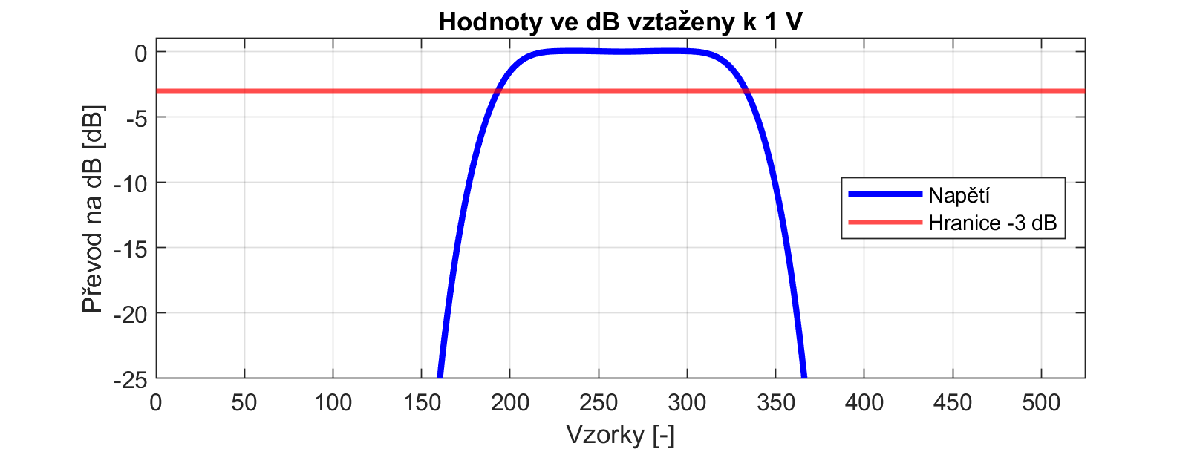

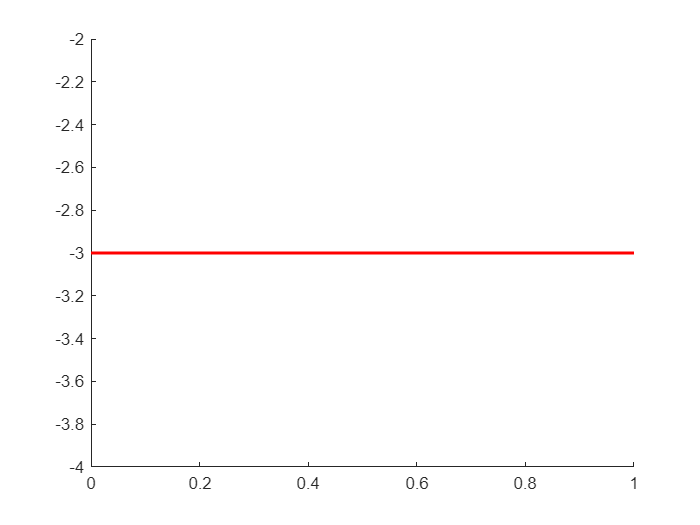

figure(4)
...
hold on
yline(-3, '-r', 'LineWidth', 1.8)
hold off

...

## 3 Odevzdání

**Odevzdávejte** tento soubor *mlx*, Vámi vytvořené funkce (v tomto cvičení: `kos_prumer) `a vytvořený PDF. PDF soubor vytvoříte tak, že nejprve necháte vygenerovat všechny výstupy ve skritpu (vykreslení obrázků, výpis pomocí `disp`, atd.). Nejsnáze přes tlačítko Run (ve skriptu samotném také ponechte výstupy). Poté v liště "**LIVE EDITOR**" v sekci "**FILE**" lze rozkliknout nabídku "**Export**", kde zvolíte "**Export to PDF...**".

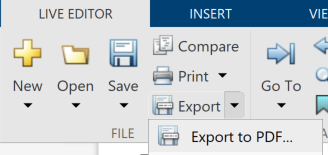

Vše zabalte do ZIP a odešlete na MOODLE v sekci "Odevzdání protokolů".